# SysMIC M1: Assignment 6

If you need help for this assignment please make use of the [session 6 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=2533).

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2414](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2414).  

After submission you can access model answers via the [session 6 review](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3232) activity.

`Name: [ Jade Lau ]`

## Exercise 1.2.7 

([section link](https://sysmic.ac.uk/textbook/1.2-enzymatic-reactions.html#1.2.3))

1. Consider the reaction in which the reaction rate $j$ can be modelled as a function of subtrate concentration $\left\lbrack S\right\rbrack$using:

   $j\left(\left\lbrack S\right\rbrack \right)=V_{\max } {\left\lbrack \frac{\left\lbrack S\right\rbrack }{K+\left\lbrack S\right\rbrack }\right\rbrack }^{n\;} \;$    where $K=1\ldotp 0,{\;V}_{\max } =10,\;n=3$

i) Use MATLAB to plot $j$ and $\frac{\mathrm{d}\;j}{\mathrm{d}\left\lbrack S\right\rbrack }$

Hint. Modify the code in the textbook example that  was used to plot $h$ and $\frac{\mathrm{d}\;h}{\mathrm{d}\left\lbrack S\right\rbrack }$ taking care to note the different value of $n$.

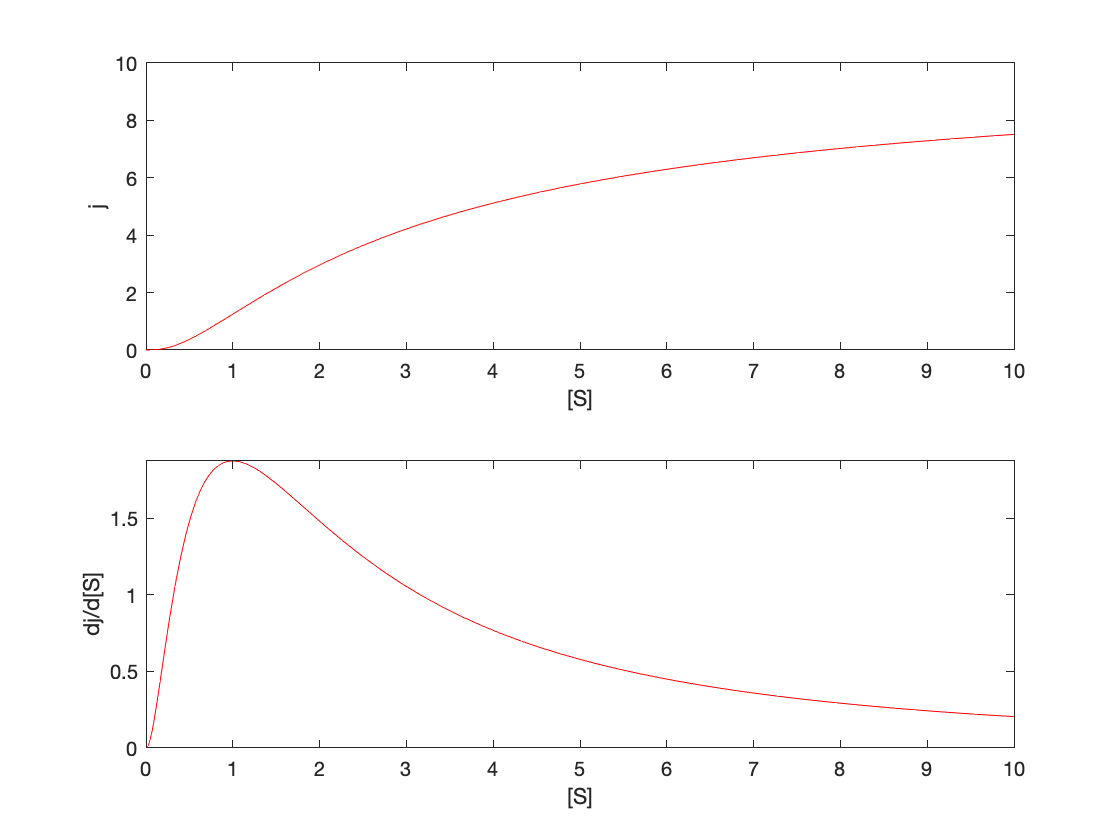

% answer 
syms S Vmax K n;
j = Vmax * (S/(K+S))^n;

dj = diff(j,S);

dj = simplify( dj );

mj = matlabFunction(j,'vars',[S,K,Vmax,n]);
mdj = matlabFunction(dj,'vars',[S,K,Vmax,n]);
f1 = @(S) mj(S,1,10,3.0);
f2 = @(S) mdj(S,1,10,3.0);
limits = [0 10];
figure()
subplot(2,1,1)
fplot(f1,limits,'r')
axis([0 10 0 10])
ylabel('j')
xlabel('[S]')
subplot(2,1,2)
fplot(f2,limits,'r')
ylabel('dj/d[S]')
xlabel('[S]')

## Exercise 1.2.8

([section link](https://sysmic.ac.uk/textbook/1.2-enzymatic-reactions.html#1.2.3))

1. Consider the reaction in which the reaction rate $j$ can be modelled as a function of subtrate concentration $\left\lbrack S\right\rbrack$using:   $j\left(\left\lbrack S\right\rbrack \right)=V_{\max } {\left\lbrack \frac{\left\lbrack S\right\rbrack }{K+\left\lbrack S\right\rbrack }\right\rbrack }^{n\;} \;$

Differentiating this gives $\frac{\mathrm{d}\;j}{\mathrm{d}\left\lbrack S\right\rbrack }$: the rate of change of $j$ as the substrate concentration $\left\lbrack S\right\rbrack$ changes.

We wish to examine $\frac{\mathrm{d}\;j}{\mathrm{d}\left\lbrack S\right\rbrack }$, in particular to find the value of  $\left\lbrack S_m \right\rbrack$, the concentration at which $\frac{\mathrm{d}\;j}{\mathrm{d}\left\lbrack S\right\rbrack }$ is a maximum.

i) Use MATLAB to find an expression for $\left\lbrack S_m \right\rbrack$.

% answer 
% part i
% to find stationary points for dh
d2j = diff(dj,S);
Sm = solve(d2j,S,'Real',true)

$$Sm = \frac{K\,n}{2}-\frac{K}{2}$$

% Sm = solve(Sm == 0, 'Real', true);


ii) Next use this to find an expression for $j\left(\left\lbrack S_m \right\rbrack \right)$, the reaction rate at which $\frac{\mathrm{d}\;j}{\mathrm{d}\left\lbrack S\right\rbrack }$ is a maximum.

% part ii
jm = Vmax * (Sm/(K+Sm))^n;
jm = simplify(jm,'IgnoreAnalyticConstraints',true);


iii) Evaluate these expressions to find $\left\lbrack S_m \right\rbrack$ and $j\left(\left\lbrack S_m \right\rbrack \right)$ with parameters $K=1\ldotp 0,{\;V}_{\max } =10,\;n=3$

Hint. Estimate the values for $\left\lbrack S_m \right\rbrack$ and $\frac{\mathrm{d}\;j}{\mathrm{d}\left\lbrack S\right\rbrack }$ from the plots drawn in the last exercise to check your answers.

% part iii
vs=subs(Sm,[K,Vmax,n],[1.0 10.0 3.0])

$$vs = 1$$


% use double() function to display the
% numerical value. 

double(vs)  

ans = 1

subs(j,[S K Vmax n],[vs 1.0 10.0 3.0]) 

$$ans = \frac{5}{4}$$

## **Exercise** 1.3.4

([section link](https://sysmic.ac.uk/textbook/1.3-bacterial-growth-2.html#1.3.1))

1. A circular colony of bacteria with radius 1000$\mu$m has bacterical density D which is dependent only on the distance $r$from the center and described by equation $D=0\ldotp 1+\frac{r}{1000}$

i) Use MATLAB to calculate the indefinite integral of the bacterial density function.

syms r;
d=2*pi*r*(0.1 + (r/1000));
int(d,r, 0, 1000)

$$ans = \frac{2300000\,\pi }{3}$$

ii) Calculate the total number of bacteria in the colony.

% answer 
2408600

ans = 2.4086e+06

## **Exercise** 1.3.6

([section link](https://sysmic.ac.uk/textbook/1.3-bacterial-growth-2.html#1.3.2))

1. A modified growth model with similar behaviour to logistic growth can be developed from the differential equation:

$\frac{\textrm{dN}}{\textrm{dt}}=r\left(N\right)N$    where    $r\left(N\right)=r_{0\;} \cdot \left(1-{\left(\frac{N}{K}\right)}^2 \right)$

For the following use parameter values $r_{0\;} =0\ldotp 0347$ and $K=1,000$. 

i) Use MATLAB to plot $\frac{\textrm{dN}}{\textrm{dt}}$for this modified model.

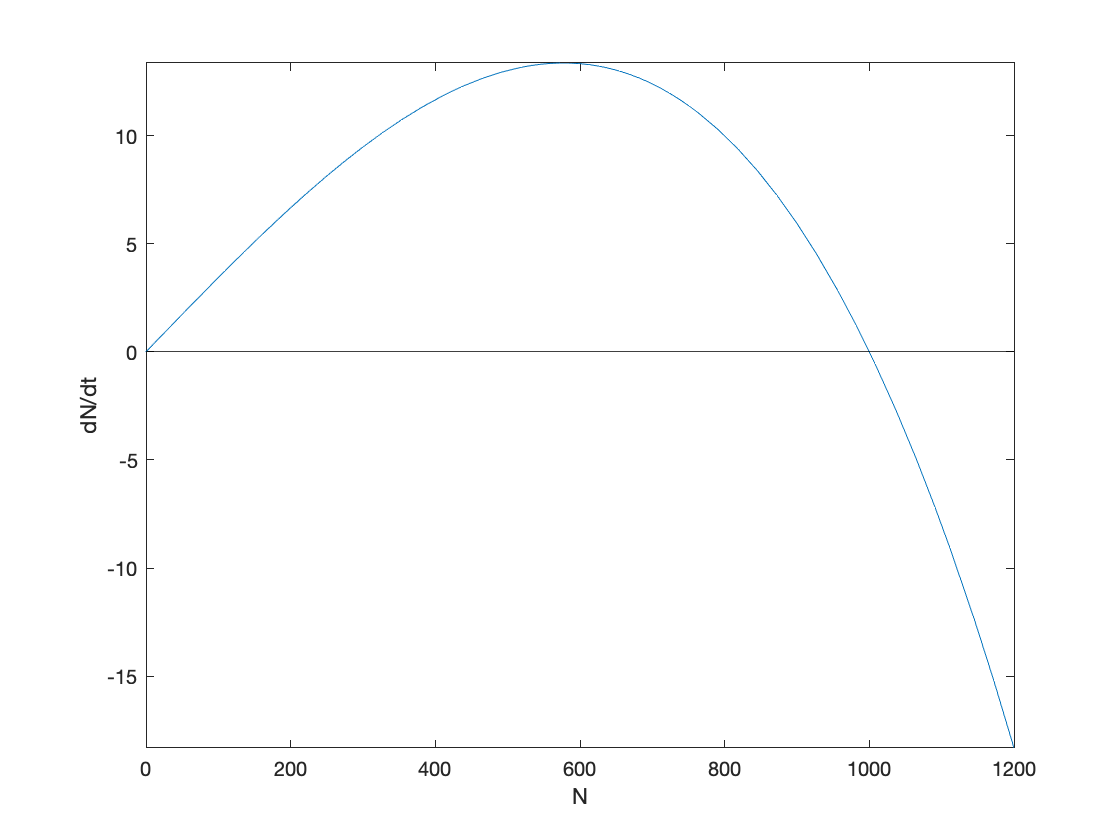

dN = @(N,r0,K) r0*N.*(1-((N./K).^2));
fun = @(N) dN(N,0.0347,1000);
limits = [0 1200];
figure()
fplot(fun,limits)
line( [0,1200], [0,0], 'Color','k' )
ylabel('dN/dt')
xlabel('N')

ii) Use this plot to infer how the population will change at different values of N.

**Comment:**

*% part ii*

*% The growth rate increases from N = 0 just before N = 600 reaching a*

*% maximum of between N = 500 and 600. The function crosses the x-axis when N = 1000, the carry*

*% capacity. When N < K, the growth rate increases, conversely when N > K the growth*

*% rate decreases.*

iii) Describe how this plot differs from the equivalent plot for the logical growth model (included below):

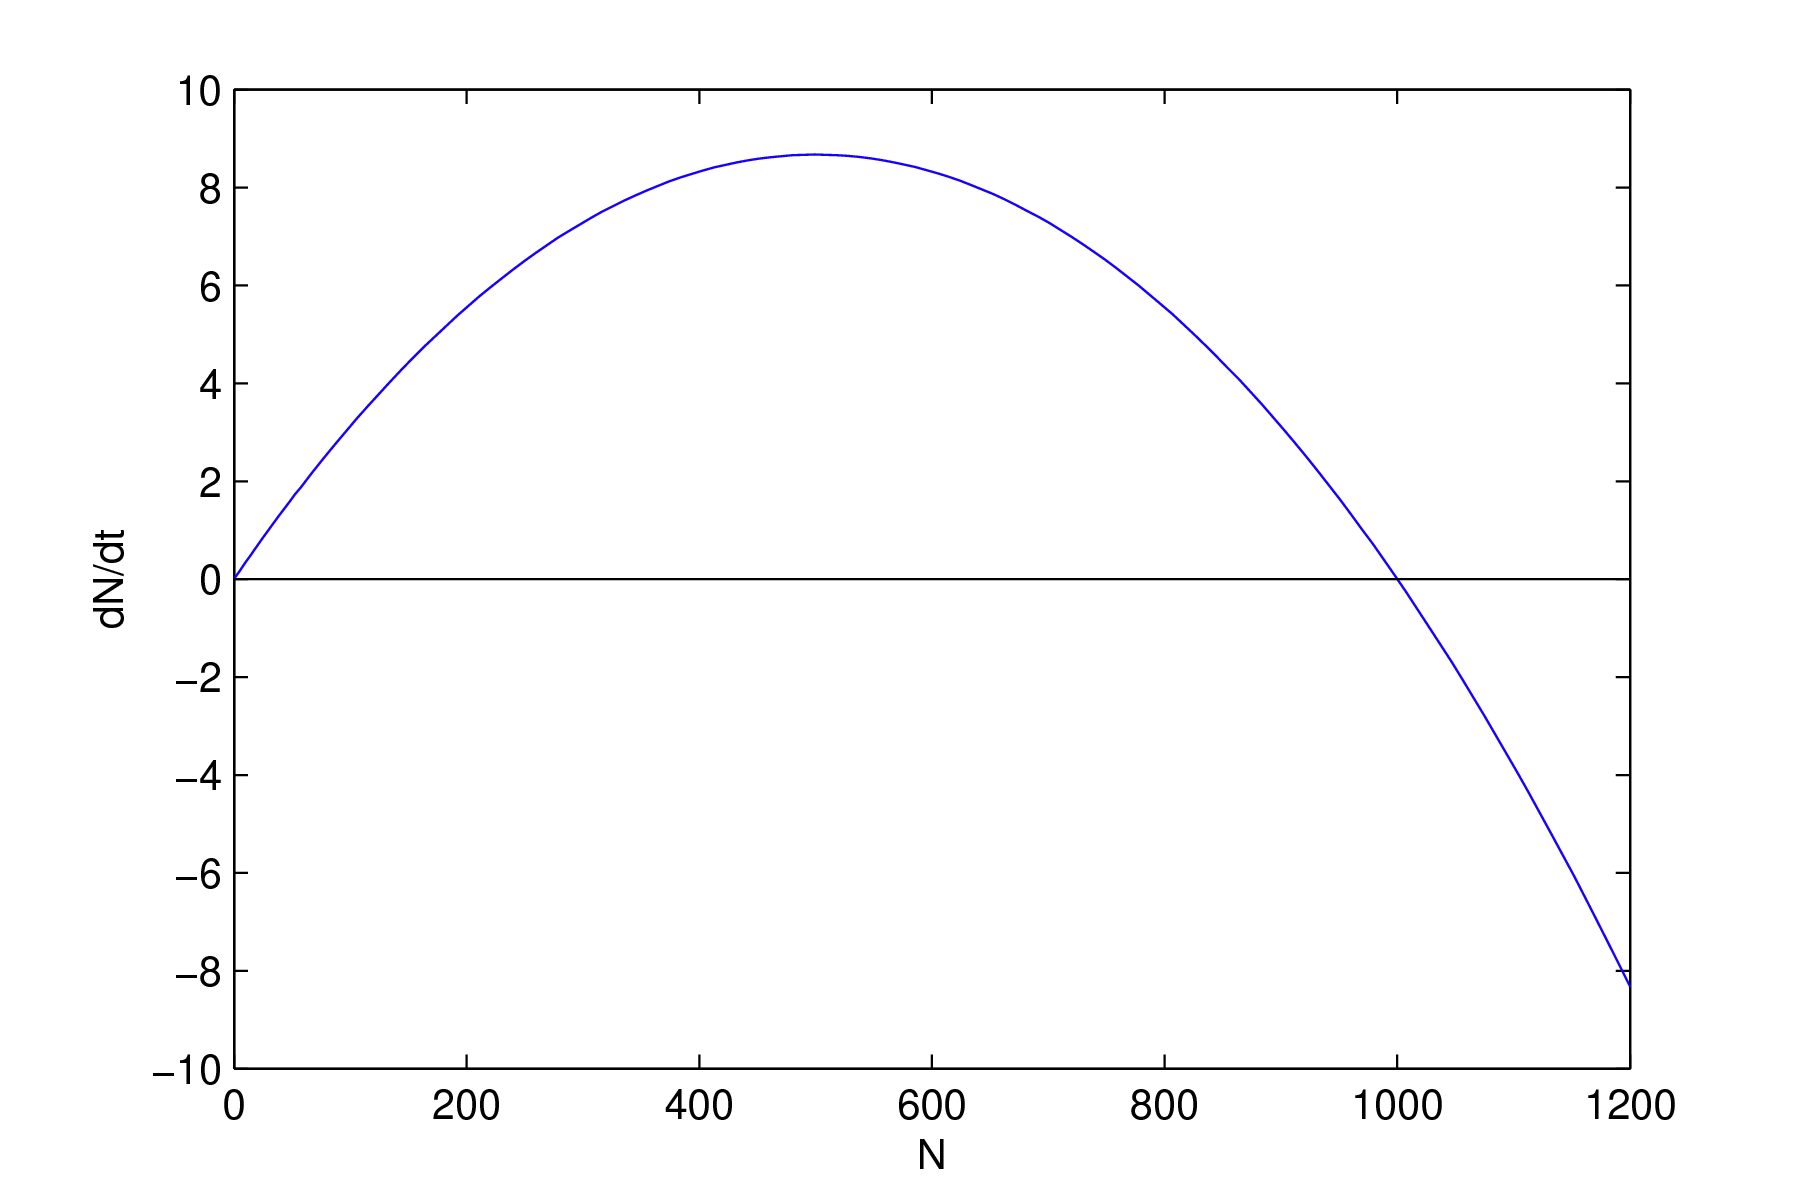

**Comment:**

*% part iii*

*% The difference between fig 1.3.3 and this plot is that 1.3.3 shows a*

*% smaller maximum, as well as a more symmetric hyperbole.*

*% The logistic growth model above dN/dt > 0 appears to increase and *

*% decrease at a similar rate whereas the modified model is skewed towards*

*% a higher population.*

*% The increase in population of the modified model is more gradual*

*% relative to the decrease that occurs after the maximum point.*

iv) Use MATLAB to find the value of N at which the growth rate is a maximum. (Hint MATLAB gives two solutions but we require N>0).

% part iv
% find the maximum of the gradient function with respect to N
syms N r0 K
f = r0*N.*(1-((N./K).^2));

df = diff(f,N);
mdf = matlabFunction(df,'vars',[N,r0,K])

mdf = function_handle with value:
    @(N,r0,K)-r0.*(1.0./K.^2.*N.^2-1.0)-1.0./K.^2.*N.^2.*r0.*2.0


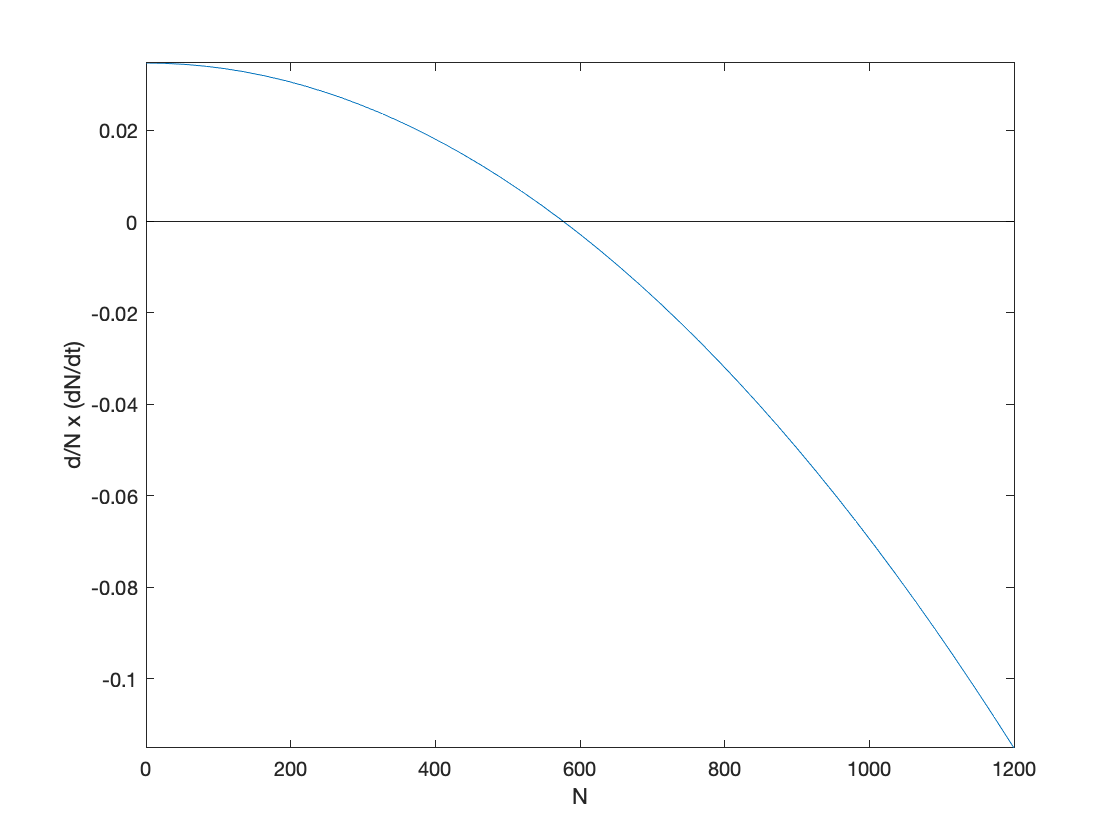

fun = @(N) mdf(N,0.0347,1000);
limits = [0 1200];
figure()
fplot(fun,limits)
line( [0,1200], [0,0], 'Color','k' )
ylabel('d/N x (dN/dt)')
xlabel('N')


solve(df==0,N)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{3}\,K}{3}\\ \frac{\sqrt{3}\,K}{3} \end{array}\right)$$


% -(3^(1/2)*K)/3
%  (3^(1/2)*K)/3



v) Find the solution of this differential equation using the dsolve command.

% part v

syms N(t) N0 r0 K;
eqn = diff(N,t) == r0*N.*(1-((N./K).^2));
cond = N(0) == N0;
N = dsolve(eqn, cond);
N = simplify(N)

$$N = \sqrt{\frac{K^{2}\,{N_{0}}^{2}\,{\mathrm{e}}^{2\,r_{0}\,t}}{K^{2}-{N_{0}}^{2}+{N_{0}}^{2}\,{\mathrm{e}}^{2\,r_{0}\,t}}}$$


% N = ((K^2*N0^2*exp(2*r0*t))/(K^2 - N0^2 + N0^2*exp(2*r0*t)))^(1/2)

solve(N==0,t);



vi) Create two figures overlaying plots showing population growth for this modified model and the logistic growth solution:

Do this for both $N_0 =100$ and $N_0 =5000\ldotp$

Hint. Modify the following code which solves the logistic growth equation and converts it to a MATLAB function:

% part vi

% Logistic growth
syms N(t) N0 r0 K t;
eqn_L = diff(N,t) == r0*N*(1-N/K);
cond = N(0) == N0;
N_L=dsolve(eqn_L, cond);
N_L=simplify(N_L)

$$N\_L = \frac{K\,N_{0}\,{\mathrm{e}}^{r_{0}\,t}}{K-N_{0}+N_{0}\,{\mathrm{e}}^{r_{0}\,t}}$$

mN_L = matlabFunction(N_L,'vars',[N0,K,r0,t]);

funN100_L = @(t) mN_L(100,1000,0.0347,t);
funN5000_L = @(t) mN_L(5000,1000,0.0347,t);

% Modified growth
syms N(t) N0 r0 K t;
eqn_M = diff(N,t) == r0*N.*(1-((N./K).^2));
cond = N(0) == N0;
N_M=dsolve(eqn_M, cond);
N_M=simplify(N_M)

$$N\_M = \sqrt{\frac{K^{2}\,{N_{0}}^{2}\,{\mathrm{e}}^{2\,r_{0}\,t}}{K^{2}-{N_{0}}^{2}+{N_{0}}^{2}\,{\mathrm{e}}^{2\,r_{0}\,t}}}$$

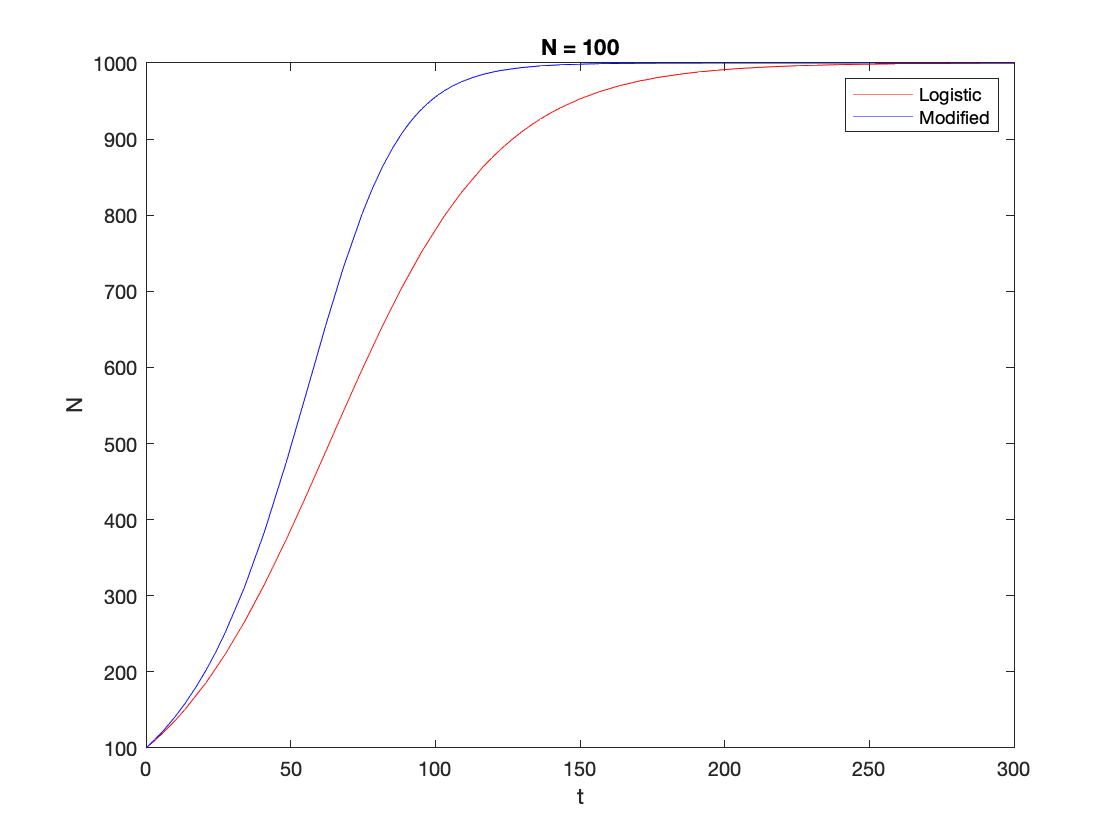

mN_M = matlabFunction(N_M,'vars',[N0,K,r0,t]);

funN100_M = @(t) mN_M(100,1000,0.0347,t);
funN5000_M = @(t) mN_M(5000,1000,0.0347,t);

% Plot

figure()
limits = [0 300];
fplot(funN100_L, limits, 'r')
hold on
fplot(funN100_M, limits, 'b')
ylabel('N')
xlabel('t')
legend('Logistic', 'Modified')
title('N = 100')

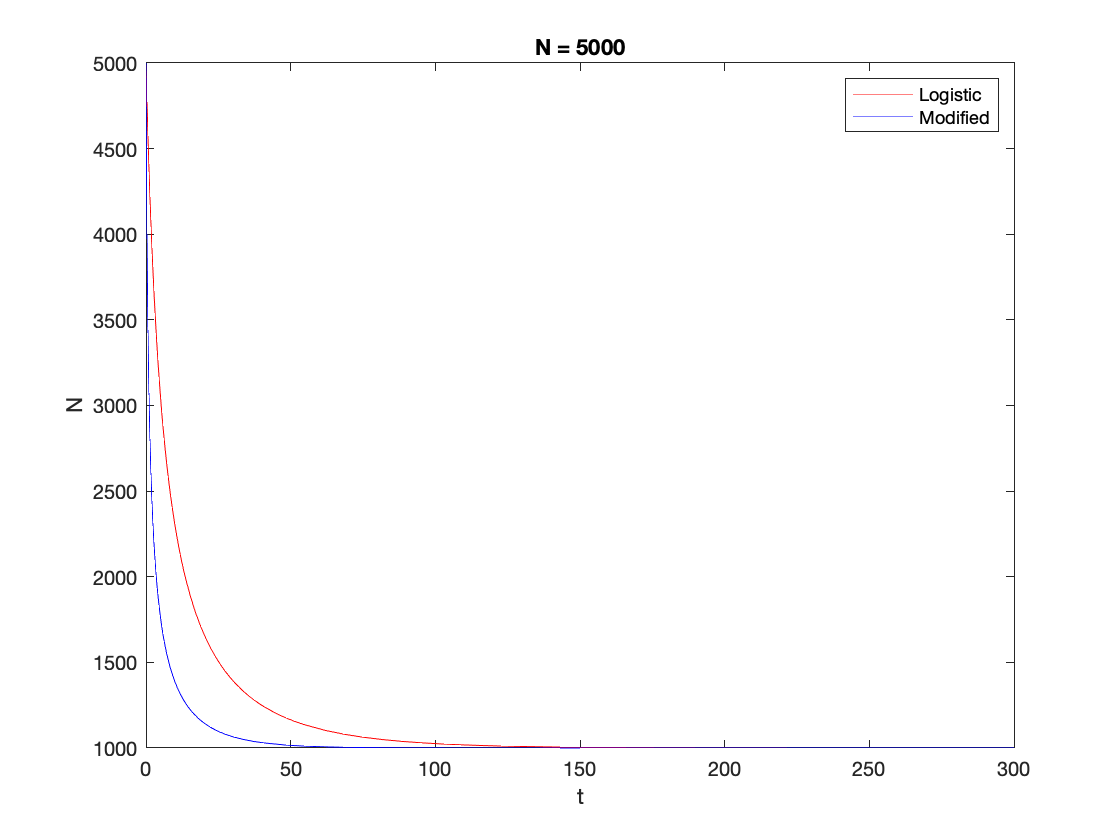



figure()
fplot(funN5000_L, limits, 'r')
hold on
fplot(funN5000_M, limits, 'b')
ylabel('N')
xlabel('t')
legend('Logistic', 'Modified')
title('N = 5000')

vii) Describe the differences between the graphs.

***Comments:***

% part vii

% When N = 100, both Logistic and Modified models increase and appear to do so at similar rates in the first 20 minutes

% however the Modified model increases faster relative to Logistic from 20

% minutes onwards. As such the Modified model reaches carrying capacity

% faster by approximately 100 minutes.

% When N= 5000, the population is way beyond carrying capacity and

% decreases exponentially. The Modifed model has a faster rate of decrease

% reaching carrying capacity 50 minutes before the Logistic model.